Let us look at which eigendirection contributes most to SNR.

In visual cortex (according to Oleg's paper), the answer is the third eigenmode of noise.

First let's load the sessions database:

org = Org;
org.load_definitions;

Let's look at session #70 first.

Look at the noise eigenvalues of the covariance matrix, the loadings of the signal vector (not unit vector) on the eigenvectors, and the SNR along each eigenvector.

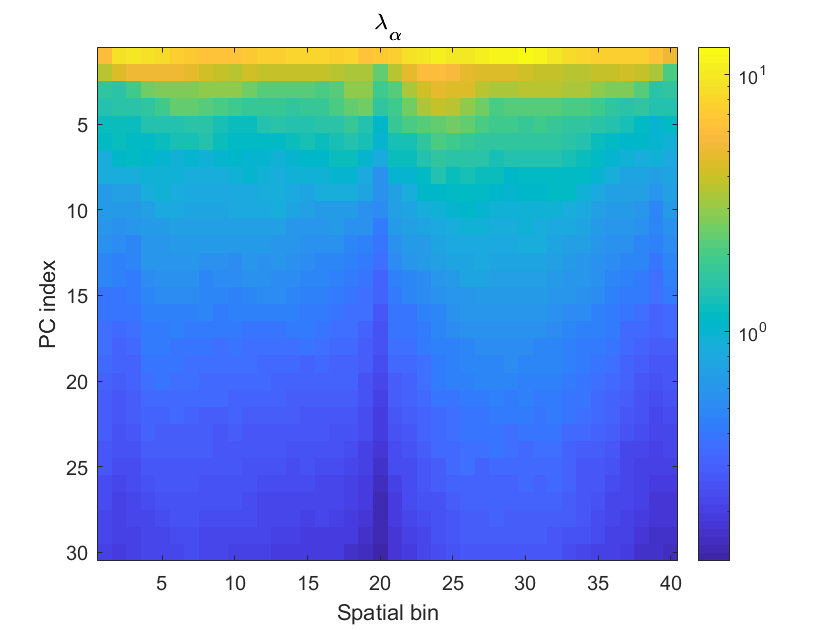

s_ID = 70;

cut = @(x)x(1:30,:);
cut_l = @(x)x(1:30);

figure;
%subplot(3,1,1);
imagesc(cut(org.sess_by_bins('lambda', s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '\lambda_\alpha'
colorbar;

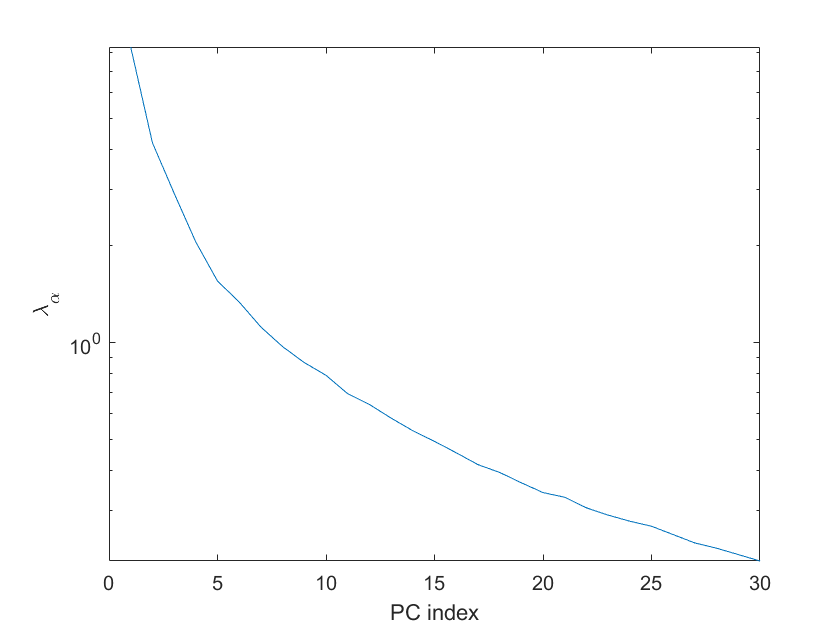

figure;
semilogy(cut_l(org.sess_med_bins('lambda', s_ID)));
xlabel 'PC index'
ylabel '\lambda_\alpha'

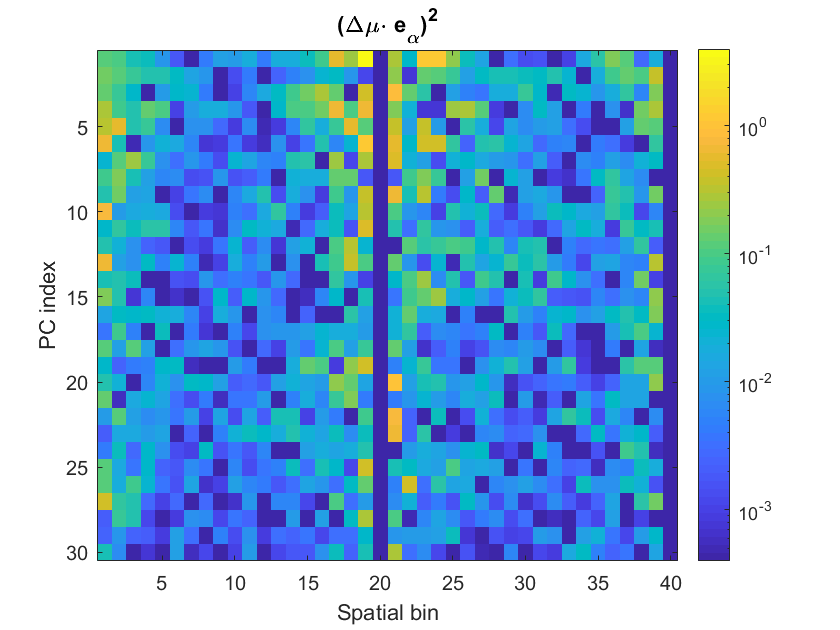


figure;%subplot(3,1,2);
imagesc(cut(org.sess_by_bins('full_loadings', s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2'
colorbar;

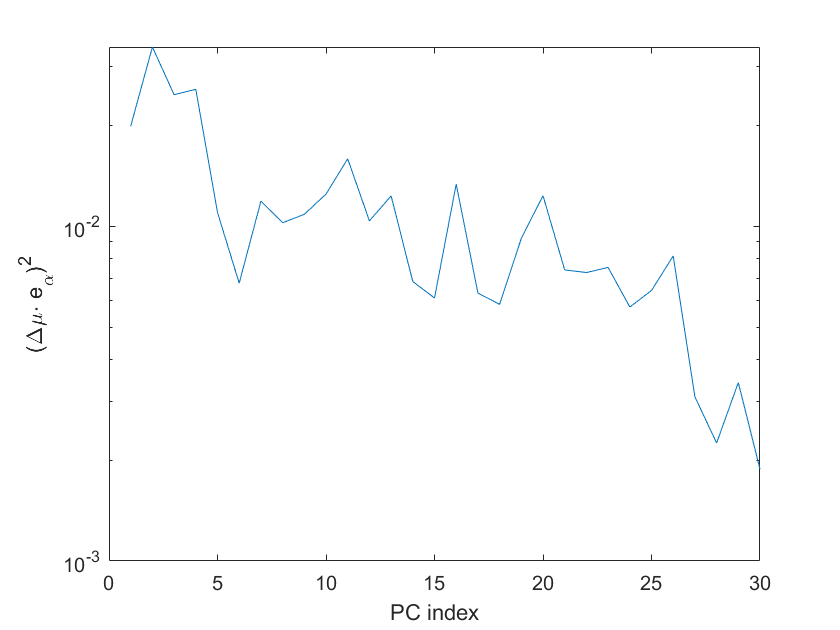

figure;
semilogy(cut_l(org.sess_med_bins('full_loadings', s_ID)));
xlabel 'PC index'
ylabel '(\Delta\mu\cdot e_\alpha)^2'

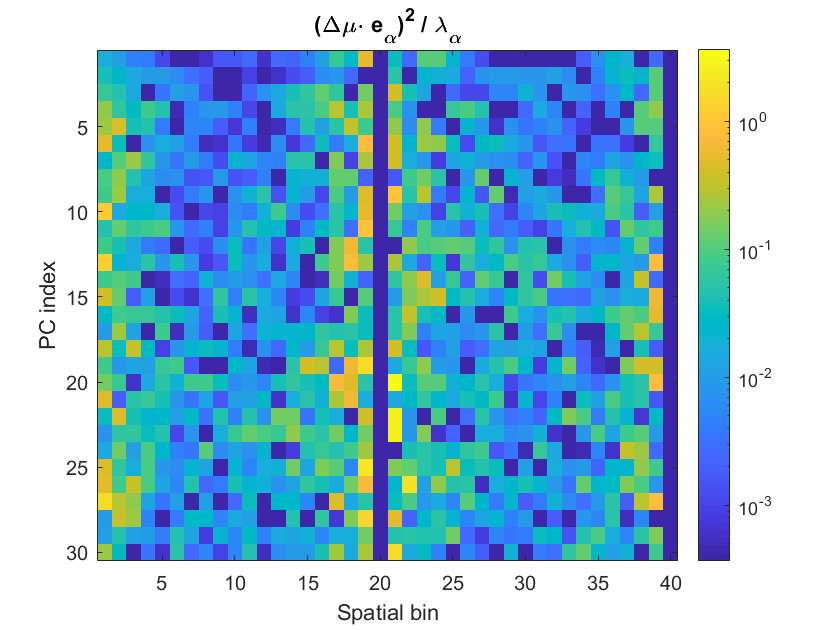



figure;%subplot(3,1,3);
imagesc(cut(org.sess_by_bins('eigen_snr',s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha'
colorbar;

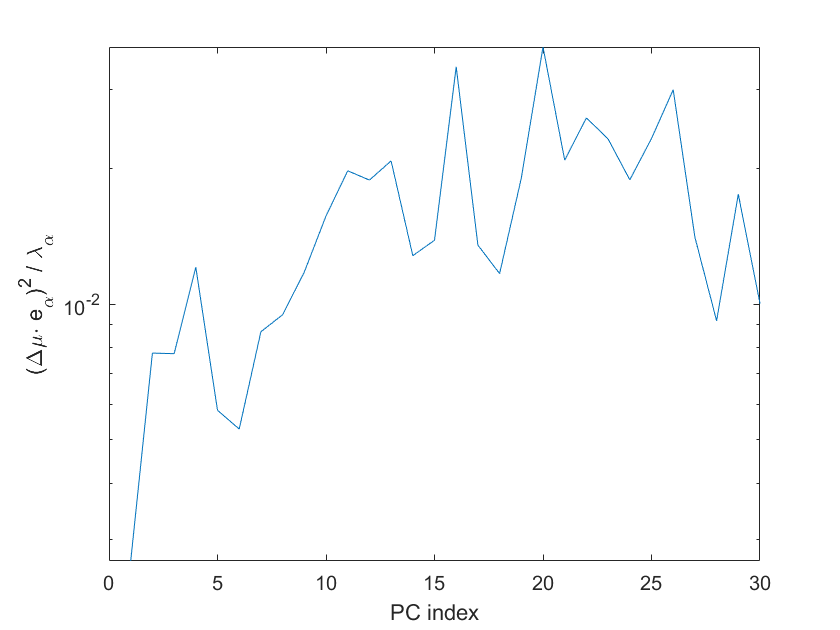

figure;
semilogy(cut_l(org.sess_med_bins('eigen_snr', s_ID)));
xlabel 'PC index'
ylabel '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha'

It looks like the earlier PCs have less SNR. Let's check if it generalizes.

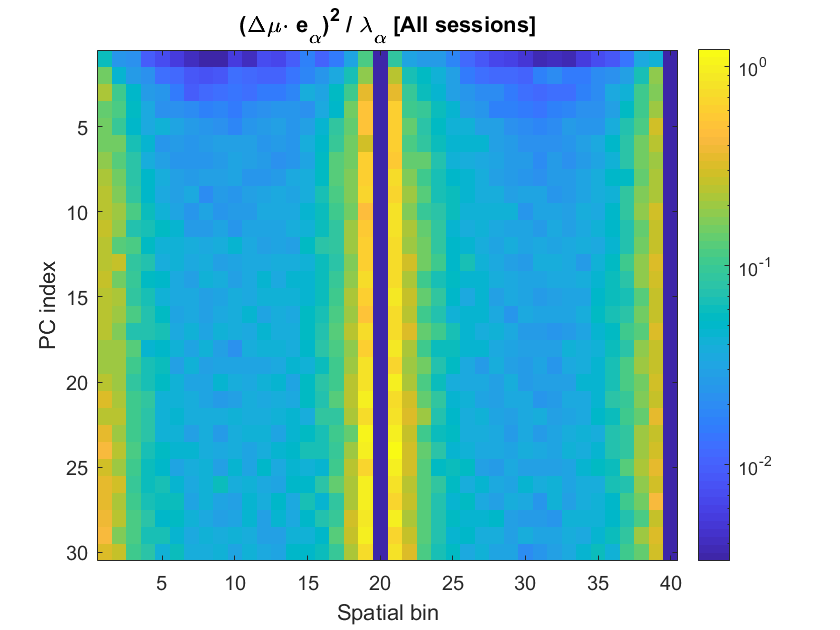

figure;
imagesc(cut(org.all_by_bins('eigen_snr')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha [All sessions]'
colorbar;

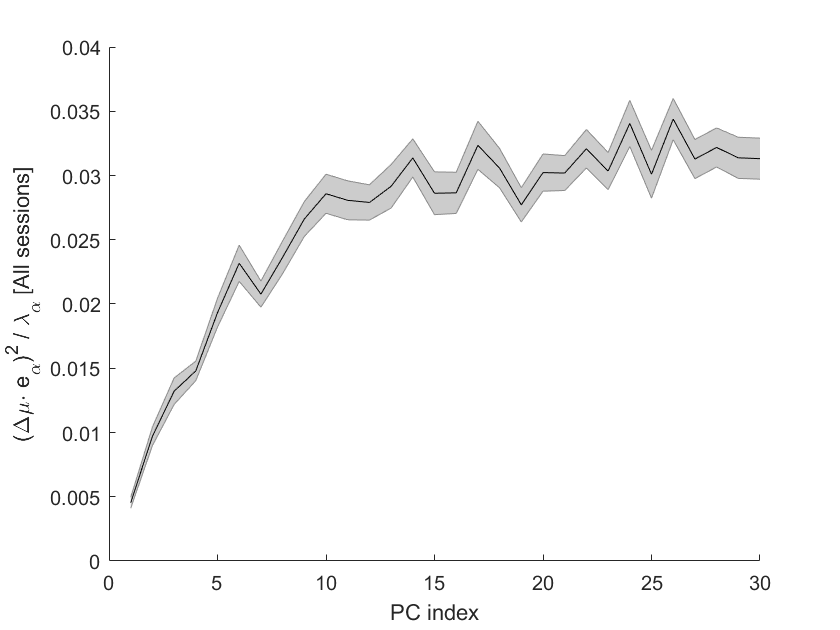

figure;
[m_,s_] = org.all_med_bins('eigen_snr');
serrorbar(cut_l(m_), cut_l(s_));
%set(gca, 'YScale', 'log');
xlabel 'PC index'
ylabel '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha [All sessions]'

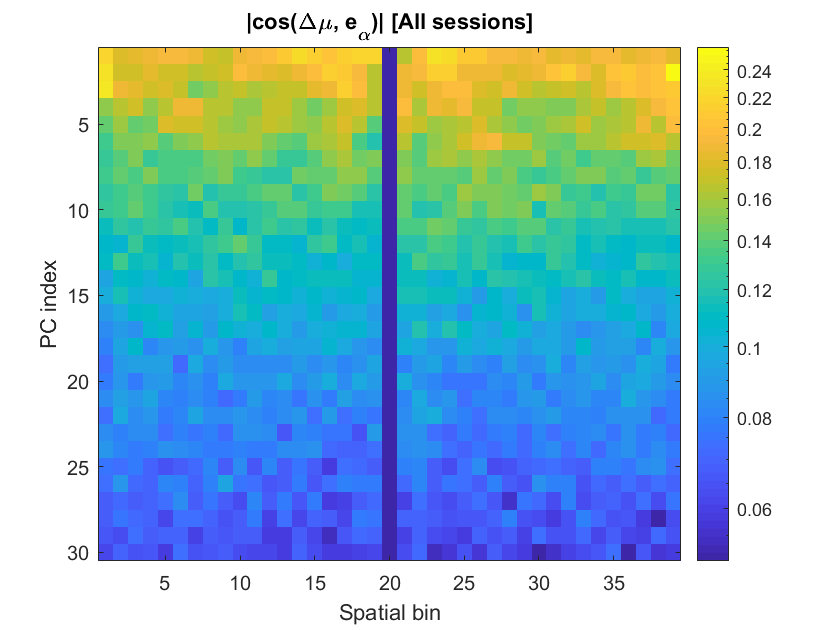



figure;
imagesc(cut(org.all_by_bins('loadings')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '|cos(\Delta\mu, e_\alpha)| [All sessions]'
colorbar;

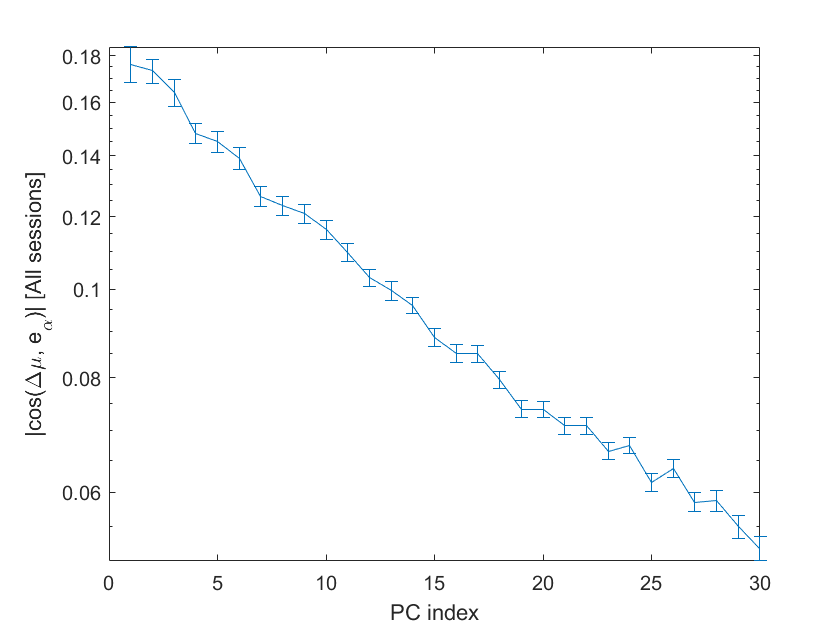

figure;
[m_,s_] = org.all_med_bins('loadings');
errorbar(cut_l(m_), cut_l(s_));
set(gca, 'YScale', 'log');
xlabel 'PC index'
ylabel '|cos(\Delta\mu, e_\alpha)| [All sessions]'

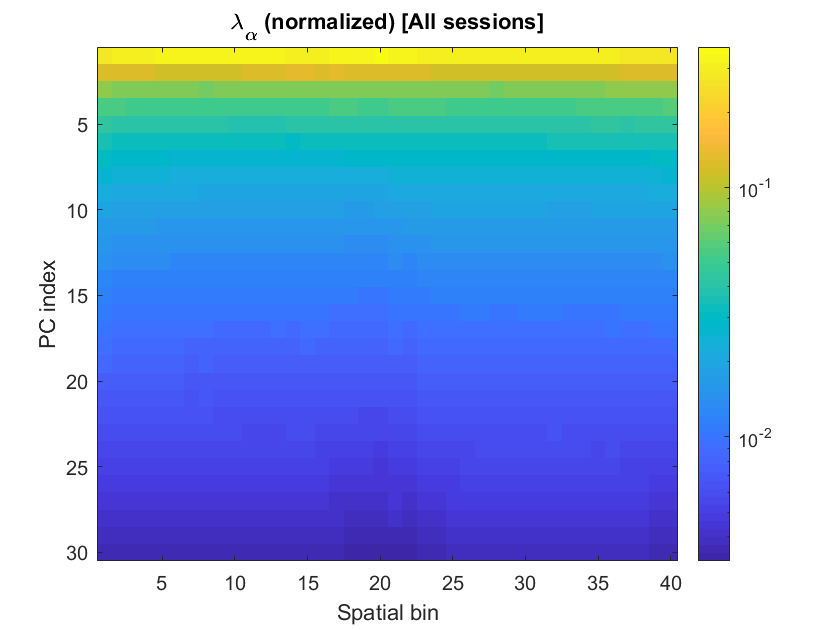


figure;
imagesc(cut(org.all_by_bins('lambda_normed')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '\lambda_\alpha (normalized) [All sessions]'
colorbar;

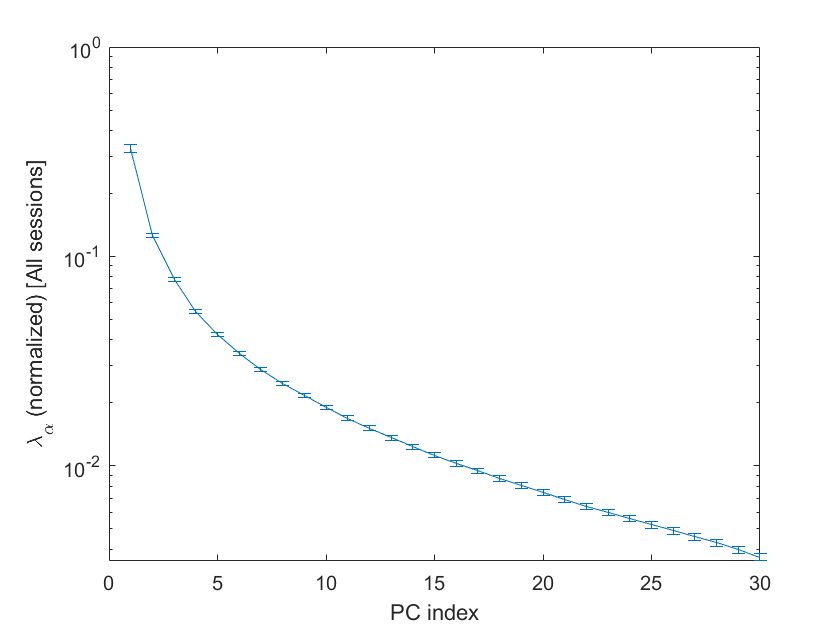


figure;
[m_,s_] = org.all_med_bins('lambda_normed');
errorbar(cut_l(m_), cut_l(s_));
set(gca, 'YScale', 'log');
xlabel 'PC index'
ylabel '\lambda_\alpha (normalized) [All sessions]'

It looks like the effect generalizes. This result is qualitatively different from the cortex.

Now let's look at the eigen SNRs for each mouse independently.

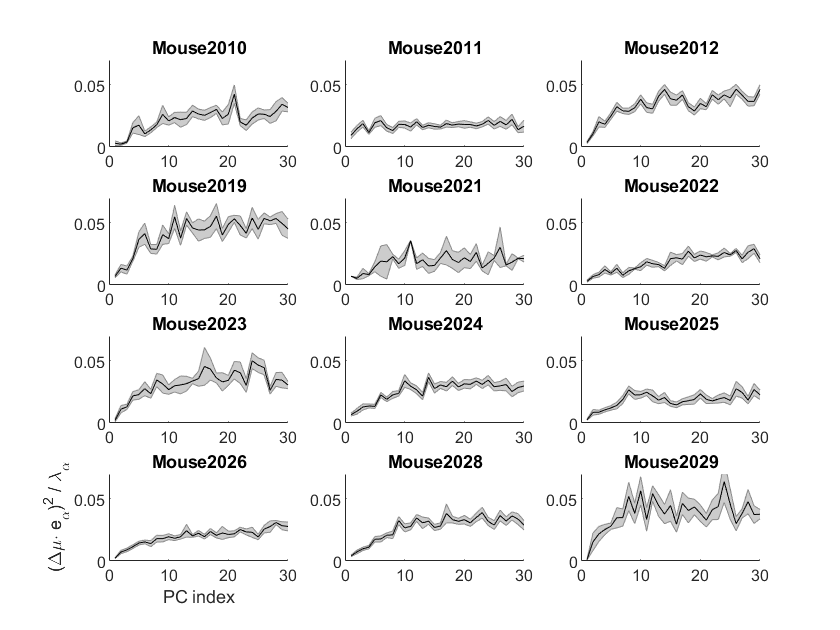

[~,mice_] = DecodeTensor.filt_sess_id_list;
mice_ = unique(mice_);
figure;
for i = 1:numel(mice_)
    subplot(4,3,i);
    [m_, s_] = org.mouse_med_bins('eigen_snr', mice_{i});
    serrorbar(cut_l(m_),cut_l(s_));
    %set(gca, 'YScale', 'log');
    %ylim([0.001 0.06]);
    ylim([0.00 0.07]);
    if i==10
        xlabel 'PC index'
        ylabel '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha'
    end
    title(mice_{i});
end

Is the distribution of signal densities across bins:

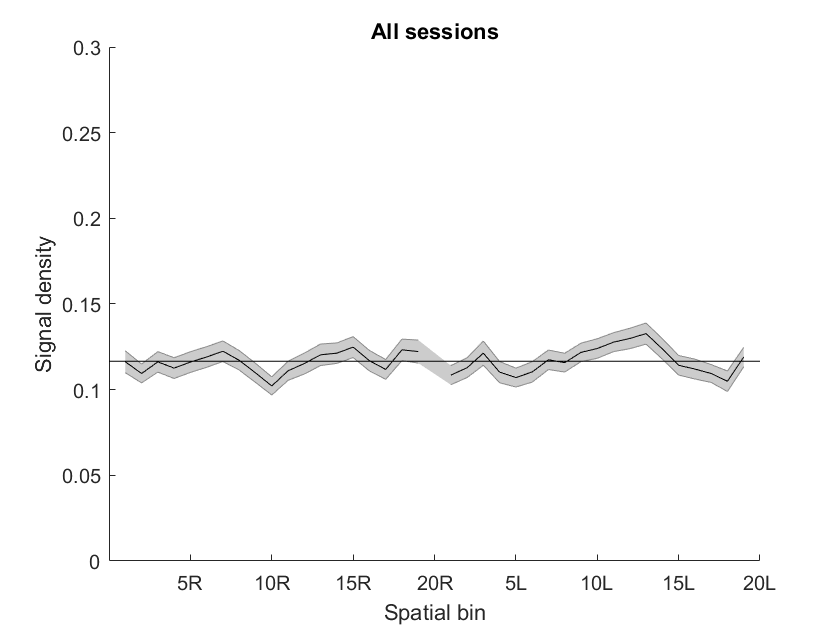

[m_,s_] = org.all_by_bins('signal_density');
figure;
serrorbar(m_,s_);
hold on;
l_ = refline([0 nanmean(m_)]); l_.Color = 'k';
xlabel 'Spatial bin'
ylabel 'Signal density'
title 'All sessions'
bin_labels = [cellfun(@(x)[num2str(x) 'R'],(num2cell(1:20)), 'UniformOutput', false),...
    cellfun(@(x)[num2str(x) 'L'],(num2cell(1:20)), 'UniformOutput', false)];
ylim([0 0.3])
show_ticks = 5:5:40;
set(gca, 'XTick', show_ticks);
set(gca, 'XTickLabels', bin_labels(show_ticks));

And for each mouse independently:

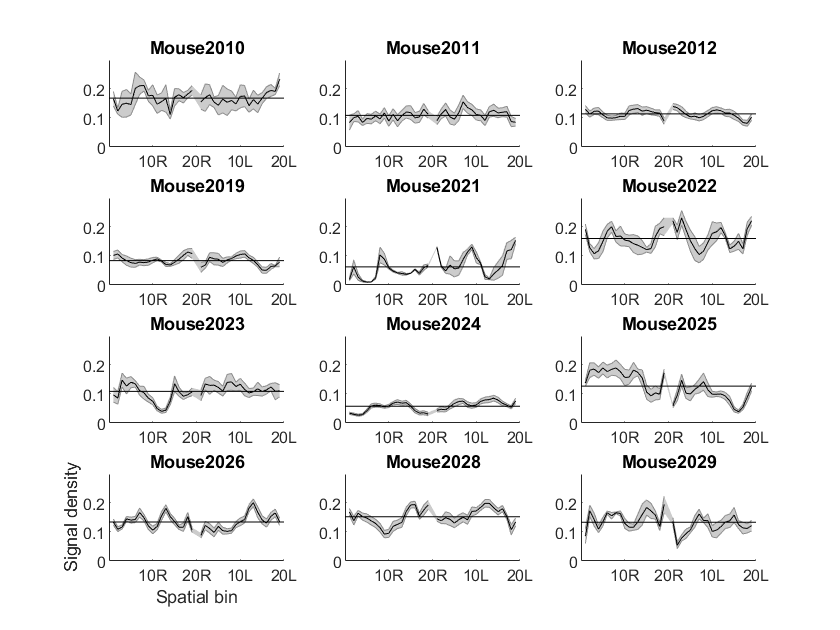

[~,mice_] = DecodeTensor.filt_sess_id_list;
mice_ = unique(mice_);
figure;
show_ticks = 10:10:40;
for i = 1:numel(mice_)
    subplot(4,3,i);
    [m_, s_] = org.mouse_by_bins('signal_density', mice_{i});
    serrorbar(m_,s_);
    hold on;
    l_ = refline([0 nanmean(m_)]); l_.Color = 'k';
    
    if i==10
        xlabel 'Spatial bin'
        ylabel 'Signal density'
    end
    ylim([0 0.3])
    set(gca, 'XTick', show_ticks);
    set(gca, 'XTickLabels', bin_labels(show_ticks));
    title(mice_{i});
end